% Problem 7: Linear fit
enzyme = 0.1:0.1:3.0;
rate = [0.83, 0.82, 1.23, 1.68, 1.33, 1.72, 2.09, 1.74, 1.91, 2.40,...
        2.58, 2.94, 2.87, 2.70, 3.15, 3.35, 3.71, 3.74, 3.62, 3.91,...
        4.26, 4.50, 4.48, 4.85, 4.81, 5.10, 5.21, 5.46, 5.59, 5.92];

coeffs = polyfit(enzyme, rate, 1);
y_fit = polyval(coeffs, enzyme);
Rsq = 1 - sum((rate - y_fit).^2) / sum((rate - mean(rate)).^2);

fprintf('Problem 7 Best fit function: %.3fx + %.3f\n', coeffs(1), coeffs(2));

Problem 7 Best fit function: 1.708x + 0.636


fprintf('R squared value: %.4f\n', Rsq);

R squared value: 0.9884


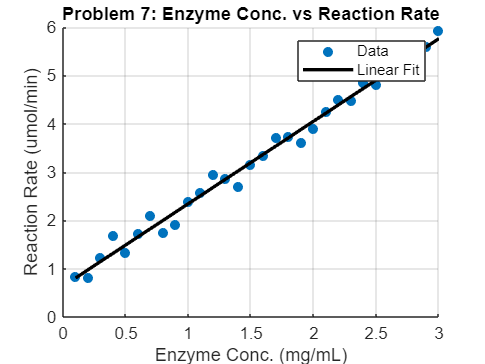


figure;
scatter(enzyme, rate, 'filled'); hold on;
plot(enzyme, y_fit, 'k', 'LineWidth', 2);
title('Problem 7: Enzyme Conc. vs Reaction Rate');
xlabel('Enzyme Conc. (mg/mL)');
ylabel('Reaction Rate (umol/min)');
legend('Data', 'Linear Fit');
grid on;